# **demo12 of Im2mesh package**

demo12 - Demonstrate function pixelMesh (pixel-based quadrilateral mesh)

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/im2mesh).

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-mesh)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## pixelMesh

pixelMesh is a function used to generate pixel-based quadrilateral mesh. It’s written by me many years ago. It’s for some special applications.

Let's start demo. First, we'll use function pixelMesh to generate mesh. In the next step, we'll export the mesh.

Import image Circle.tif.

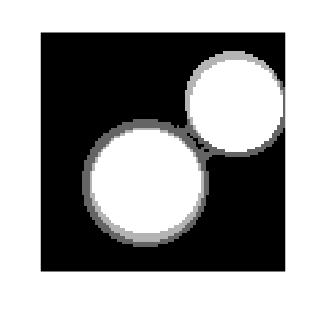

im = imread('Circle.tif');
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

Generate mesh.

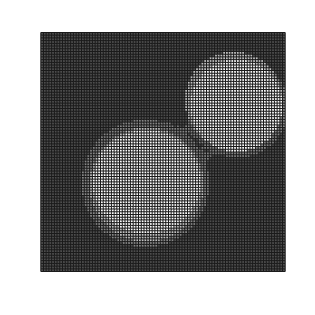

[ vert, ele, tnum, vert2, ele2 ] = pixelMesh( im );
plotMeshes( vert, ele, tnum )

Zoom in.

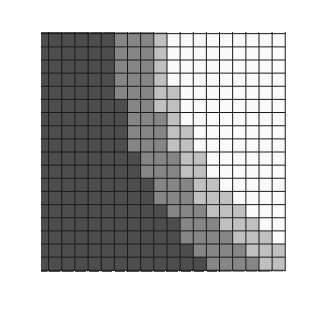

plotMeshes( vert, ele, tnum )
xlim([9.9 28.5])
ylim([15.4 33.6])

## Phase selection before meshing

The syntax of function pixelMesh is the same as function im2mesh. We can specify phase selection before meshing

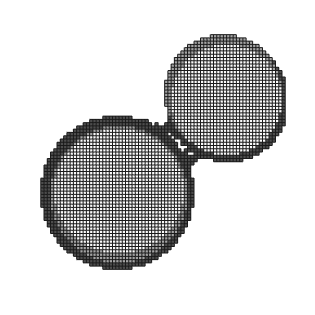

opt.select_phase = [2 3 4];
[ vert, ele, tnum, vert2, ele2 ] = pixelMesh( im, opt );
plotMeshes( vert, ele, tnum )

Zoom in.

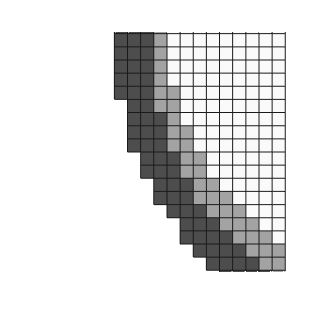

plotMeshes( vert, ele, tnum )
xlim([9.9 28.5])
ylim([15.4 33.6])

## Outputs of pixelMesh

vert is mesh nodes (for linear element)

ele is mesh elements (for linear element)

tnum is label of phase

vert2 is mesh nodes (for quadratic element)

ele2 is mesh elements (for quadratic element)

## Export mesh

We have demonstrated how to do this in demo03

### Scale node coordinates

Setup scale.

% physical dimensions of a pixel in the image
dx = 1; dy = 1; 

Scale node coordinates according to dx and dy.

% scale node coordinates of linear elements
vert( :, 1 ) = vert( :, 1 ) * dx;
vert( :, 2 ) = vert( :, 2 ) * dy;

% scale node coordinates of quadratic elements
vert2( :, 1 ) = vert2( :, 1 ) * dx;
vert2( :, 2 ) = vert2( :, 2 ) * dy;

### Export mesh as bdf file (Nastran bulk data)

precision_nodecoor = 8;
file_name = 'test_2d.bdf';

printBdf2d( vert, ele, tnum, [], precision_nodecoor, file_name );

printBdf2d Done! Check the bdf file!


### Export mesh as inp file (Abaqus)

#### Linear element

ele_type = 'CPS4';
precision_nodecoor = 8;
file_name = 'test_linear.inp';

printInp2d( vert, ele, tnum, ele_type, precision_nodecoor, file_name );

printInp2d Done! Check the inp file!


#### Quadratic element

ele_type = 'CPS8';
precision_nodecoor = 8;
file_name = 'test_quadratic.inp';

printInp2d( vert2, ele2, tnum, ele_type, precision_nodecoor, file_name );

printInp2d Done! Check the inp file!


## Comments

You will find that when exporting mesh, the functions for triangular and quadrilateral mesh is the same. That's very convenient.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo